Plik należy odplaić z folderu uklad-sterowania-lotem-b767

clear all
load("data\longitudinal_dimnsional_derivatives.mat")
load("data\longitudinal_data.mat","alfa_1")
load("data\enviroment_data.mat","v_sound")
load("data\flight_cases_data.mat","mach")
r= 1;
c=2;
g= 32.17;%ft/s^2
theta_1 = alfa_1(r, c); 
Vp1 = v_sound(r,c)*mach(2);

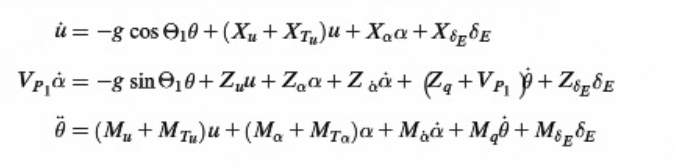

%Macierz A
Au = [(Xu(r,c)+Xtu(r,c)), Xalpha(r,c) 0 ,-g*cos(theta_1)];
Aalpha = [Zu(r,c), Zalpha(r,c) , (Zq(r,c)+Vp1), -g*sin(theta_1)]/(Vp1-Zalphadot(r,c));
Aq = [Mu(r,c)+Mtu(r,c)+Malphadot(r,c)*Aalpha(1),Malpha(r,c)+Mtalpha(r,c)+Malphadot(r,c)*Aalpha(2),Mq(r,c)+Malphadot(r,c)*Aalpha(3),Malphadot(r,c)*Aalpha(4)];
Atheta = [0,0,1,0];
A = [Au;Aalpha;Aq;Atheta];
%Macierz B
B= [XdeltaE(r,c);ZdeltaE(r,c)/(Vp1-Zalphadot(r,c));ZdeltaE(r,c)*Malphadot(r,c)/(Vp1-Zalphadot(r,c))+MdeltaE(r,c);0];
%Macierz C
C = [0,0,1,0;0,0,0,1;];
C1= [1,0,0,0;0,1,0,0;0,0,1,0;0,0,0,1;];
C2 = [0,0,1,0]

C2 =      0     0     1     0


%Macierz D
D = [0;0;0;0];

st = {'u','\alpha','q','\theta'};
in = {'\delta_{E}'};
out= {'q_{out}','\theta_{out}'};
out1 = {'u_{out}','\alpha_{out}','q_{out}','\theta_{out}'};
out2= {'q_{out}'};
M  = ss(A,B,C1,D, 'inputname', in , 'statename', st, 'outputname', out1 )

M =
 
  A = 
                    u      \alpha           q      \theta
   u         -0.01117       17.83           0      -32.09
   \alpha  -0.0003786     -0.9223      0.9573   -0.005401
   q        0.0002252      -1.976      -1.033    0.001507
   \theta           0           0           1           0
 
  B = 
           \delta_{E}
   u                0
   \alpha    -0.05585
   q           -1.676
   \theta           0
 
  C = 
                      u  \alpha       q  \theta
   u_{out}            1       0       0       0
   \alpha_{out}       0       1       0       0
   q_{out}            0       0       1       0
   \theta_{out}       0       0       0       1
 
  D = 
                 \delta_{E}
   u_{out}                0
   \alpha_{out}           0
   q_{out}                0
   \theta_{out}           0
 
Continuous-time state-space model.



Serwomecahnizm:

serwo = tf(10,[1,10]);
SM = serwo * M ;

Pętla sprzężenia zwrotnego - układ stabilizacji:

k = -0.825;
k2 = -1.61;
SAS_model_1 = feedback(SM,k2,1,3,-1);
SAS_model_2 = feedback(SM,k,1,3,-1);

Regulator PI

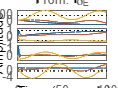

Kp = -3;
Ki = -1.2;
Kd=0 ;
Tf =0 ;
C = pid(Kp,Ki,Kd,Tf);
C1  = pid(0.1,-0.010,-Kd,Tf);
reg_model = SAS_model_2*C;
fullmodel1 = feedback(SAS_model_2*C1,1,1,4,-1);
fullmodel =  feedback(reg_model,1,1,4,-1);
step(fullmodel,fullmodel1,SM,100)

Ocena parametrów lotnych (stabilizacja):

[wn,zeta,pole] = damp(SAS_model_2);
for i = 1:4 
    if zeta(i)> 0.04 && i<=2
        disp("1 poziom akceptowalności fugoidy")
    end
    if zeta(i)>0.3 && zeta(i) < 1.3 && i>2
        disp("1 poziom akceptowalności ruchu krótkookresowego")
    end    
end

1 poziom akceptowalności fugoidy
1 poziom akceptowalności fugoidy


1 poziom akceptowalności ruchu krótkookresowego
1 poziom akceptowalności ruchu krótkookresowego
